clear all
close all

addpath('../dsfo_toolbox/');

Solve the Trace Ratio Optimization (TRO) problem, given by:


$$\text{arg}\max_X\frac{\mathbb{E}[||X^T\mathbf{y}(t)||^2]}{\mathbb{E}[||X^T\mathbf{v}(t)||^2]}\\
\text{s.t. } X^TX=I,$$


in a distributed context using the Distributed Signal Fusion Optimization (DSFO) framework.

Let us first define the network. We take a randomly connected network with 30 nodes and 15 channels per node.

nbnodes=30;
nbsensors_vec=15*ones(nbnodes,1);
nbsensors=sum(nbsensors_vec);
adj=randi(2,nbnodes,nbnodes)-1;
graph_adj=triu(adj,1)+tril(adj',-1);
non_connected=find(all(graph_adj==0));
% If there are non-connected nodes, connect them to every other node.
if(non_connected)
    graph_adj(:,non_connected)=1;
    graph_adj(non_connected,:)=1;
end

Next, we create the data using 

found at the end of this file. The number of time samples of the signals is 10000 and we choose the number of filters to be equal to 5, i.e., $X$ has 5 columns.

nbsamples=10000;
[Y,V]=create_data(nbsensors_vec,nbnodes,nbsamples);
Q=5;

The data are stored in 4 different cells, 

- One for the (stochastic) signals. In this example, the cell contains two elements, the signals $\mathbf{y}$ and $\mathbf{v}$. 

Y_cell=cell(2,1);
Y_cell{1}=Y;
Y_cell{2}=V;

- One for deterministic constant matrices. In this example, we do not have any.

B_cell={};

- One for quadratic terms. Here, we have only one, which is the identity matrix found in the constraint $X^T(I)X$.

Gamma_cell{1}=eye(nbsensors);

- The final one for global constraint parameters, i.e., those that are not filtered using $X$. In this case, we do not have any.

Glob_Const_cell={};

We then create structures for the data, problem parameters and stopping criteria called 

respectively:

data=struct;
data.Y_cell=Y_cell;
data.B_cell={};
data.Gamma_cell=Gamma_cell;
data.Glob_Const_cell={};

prob_params=struct;
prob_params.nbsensors=nbsensors;
prob_params.Q=Q;
prob_params.nbnodes=nbnodes;
prob_params.nbsensors_vec=nbsensors_vec;
prob_params.nbsamples=nbsamples;
prob_params.graph_adj=graph_adj;

We fix the number of iterations the DSFO algorithm will perform to 200.

conv=struct;
conv.nbiter=200;

We choose a randomly selected updating order for the distributed implementation:

prob_params.update_path=randperm(nbnodes);
prob_params.update_path

ans =     23    19     5    29     9     4    25    18     2    28    21    14     7    20     6    13    27    26    24    17    22    30    10    16     8     3    15    11     1    12


Then, an optimal filter $X^*$ solving the TRO problem is estimated using the centralized algorithm: 

Note that any sign change on the columns of $X^*$ is also a valid solution.

[X_star,f_star]=tro_solver(prob_params,data);
prob_params.X_star=X_star;
% Compute the distance to X^* if "true". 
prob_params.compare_opt=true;
% Show a dynamic plot if "true".
prob_params.plot_dynamic=false;

The distributed implementation is then called using the function 

 which takes as parameters the data, problem parameter and stopping criteria structures along with the functions 

which evaluates the TRO objective given a certain $X$, solves the centralized TRO problem and resolves the uniqueness ambiguity of the TRO, respectively.

[X_est,norm_diff,norm_err,f_seq]=dsfo(prob_params,data,...
        @tro_solver,conv,@tro_select_sol,@tro_eval);

Let us plot the normalized error $\epsilon$ given by:

$\epsilon(X^i)=\frac{||X^i-X^*||_F^2}{||X^*||_F^2}$,

which is stored in

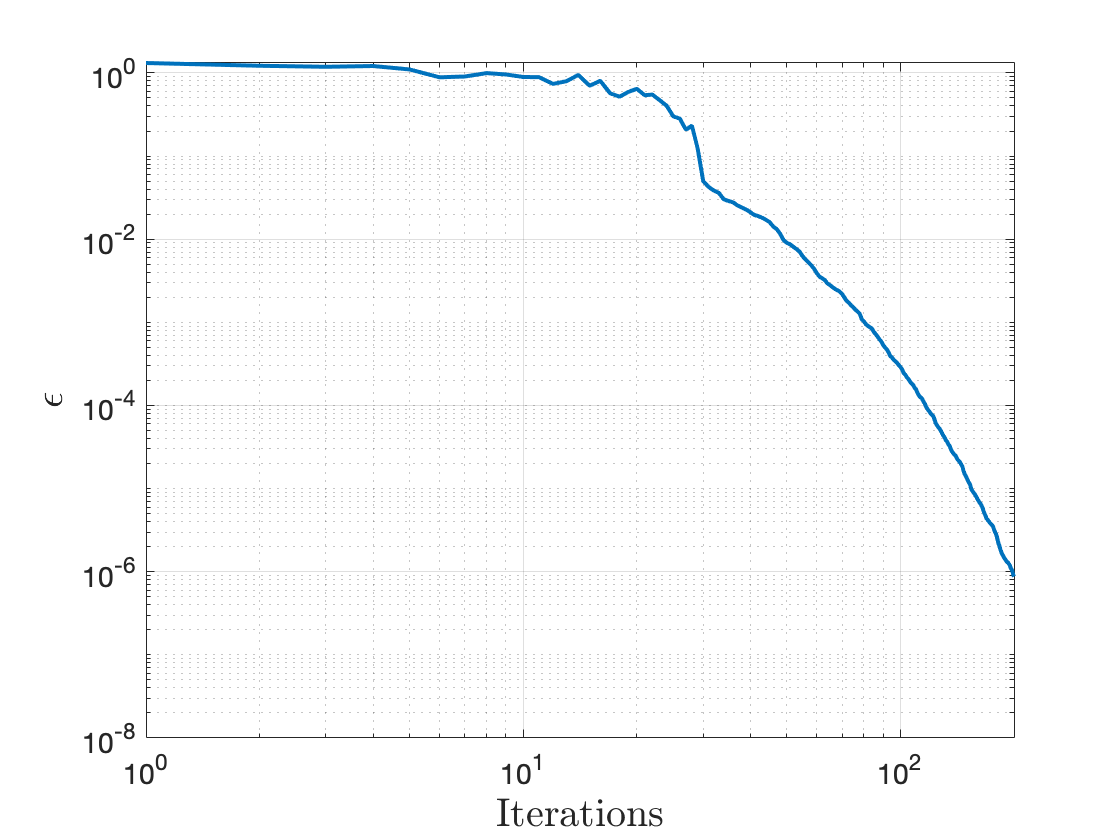

loglog([1:200],norm_err,'LineWidth',2)
ax=gca;
ax.FontSize=14;
xlim([1,inf])
ylim([1e-8,inf])
xlabel('Iterations','Interpreter','latex','Fontsize',20)
ylabel('$\epsilon$','Interpreter','latex','Fontsize',20)
grid on

Function used to create the signals $\mathbf{y}$ and $\mathbf{v}$.

function [Y,V]=create_data(nbsensors_vec,nbnodes,nbsamples)
    
    noisepower=0.1;
    signalvar=0.5;
    nbsources=5;
    latent_dim=10;
    offset=0.5;

    rng('shuffle');
    D=randn(nbsources,nbsamples);
    D=sqrt(signalvar)./(sqrt(var(D,0,2))).*(D-mean(D,2)*ones(1,nbsamples));
    S=randn(latent_dim-nbsources,nbsamples);
    S=sqrt(signalvar)./(sqrt(var(S,0,2))).*(S-mean(S,2)*ones(1,nbsamples));

    for k=1:nbnodes
        A{k}=rand(nbsensors_vec(k),nbsources)-offset;
        B{k}=rand(nbsensors_vec(k),latent_dim-nbsources)-offset;
        noise{k}=randn(nbsensors_vec(k),nbsamples); 
        noise{k}=sqrt(noisepower)./sqrt(var(noise{k},0,2)).*(noise{k}...
            -mean(noise{k},2)*ones(1,nbsamples)); 
    end

    column_blk=0;

    Y_cell=cell(nbnodes,1);
    V_cell=cell(nbnodes,1);
    
    for k=1:nbnodes
        V_cell{k}=B{k}*S+noise{k};
        Y_cell{k}=A{k}*D+V_cell{k};

        Y(column_blk+1:column_blk+nbsensors_vec(k),1:nbsamples)=Y_cell{k};
        V(column_blk+1:column_blk+nbsensors_vec(k),1:nbsamples)=V_cell{k};
        column_blk=column_blk+nbsensors_vec(k);
    end

end